# Praktikum 7 - Shift 1 Selasa

`23 November 2021`

`Nama : Carolina Sinaga`

`NIM  : 10119050`

## Nomor 1

Diberikan suatu persamaan difusi sebagai berikut:

#### 
$$u_t=cu_{xx}, \;\;\;\;\;0<x<L,\;\; 0<t\leq T$$


#### 
$$u(x,0)=f(x), \;0\leq x\leq L$$


#### 
$$u_x(0,t)=\alpha, u(L,t)=\beta$$


dengan $\alpha, \beta$ suatu konstanta. 

Misalkan $r=\frac{c\Delta t}{\Delta x^2}$.  Selang $[0,L]$ dan $[0,T]$ masing - masing dipartisi menjadi $N_x$ dan $N_t$ buah subselang. Dengan menggunakan metode `Backward Time Centered Space (BTCS)`, diperoleh suatu sistem persamaan linear $A\vec{U}_{j+1}=\vec{B}_j$ dengan $\vec{U}_{j+1}=\left[u_0^{j+1}, u_1^{j+1}, .., u_{N_{x-1}}^{j+1} \right]^T$, suatu matriks berukuran $N_x \times 1$.  Tuliskan matriks $A$ dan $\vec{B}_j$ dari SPL tersebut !

#### Jawaban : (Jawaban dapat diketik/difoto)

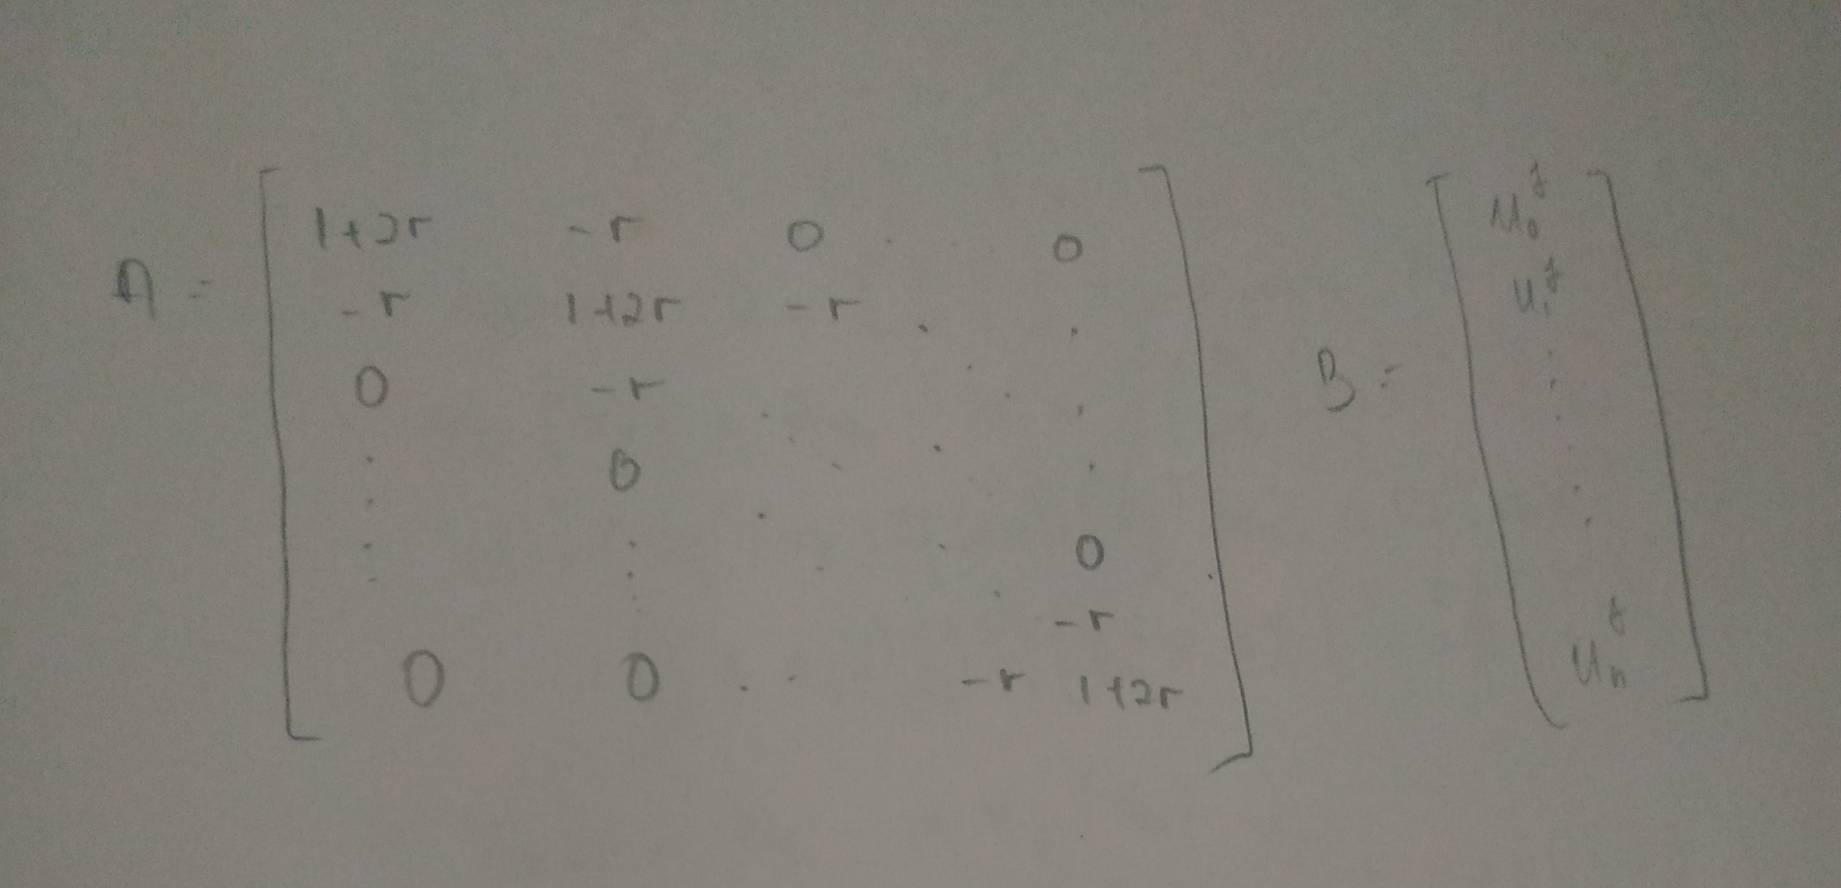

## Nomor 2

Bangun suatu fungsi `diff_BTCS` yang menerima masukan $c, f(x), \alpha,\beta, N_x, N_t, L, T$ untuk menyelesaikan persamaan difusi pada Nomor 1. Gunakanlah SPL yang sudah kamu peroleh.

`Keterangan :`

- $c,L,T$ bilangan real positif.

- $f(x)$ fungsi (gunakan anonymous function).

- $\alpha, \beta$ suatu konstanta.

- $Nx, N_t$ bilangan asli.

- Gunakanlah perintah `linsolve(A,B)` pada MATLAB untuk memperoleh solusi $X$ dari SPL $AX=B$

Keluaran dari fungsi tersebut adalah matriks $U_{(N_x+1)\times(N_t+1)}$, yaitu solusi $u_i^j$ untuk $i=0,1,2,...,N_x$ dan $j=0,1,.., N_t$. 

## Nomor 3

Run code pada section dibawah ini, dan amati animasi dari plot yang muncul. 

Apa yang dapat kamu interpretasikan? Berapakah nilai $\lim_{t\to\infty}u(x,t)$?

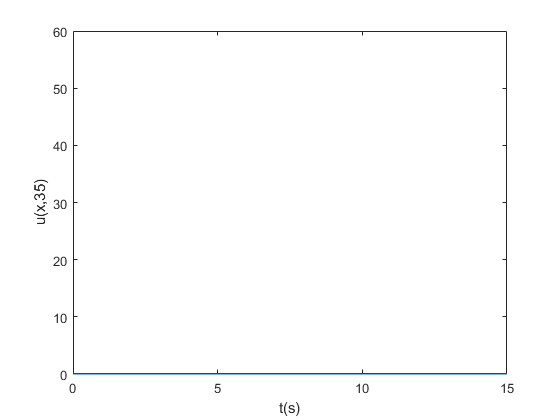

% Run Section ini.
c = 5;
L = 15;
T = 35;
f = @(x) 50-x.^2/15;
Nx = 30;
Nt = 50;
alpha = 0;
beta = 35;
U = diff_BTCS(c, L, T, f, alpha, beta, Nx, Nt);
X = linspace(0,Nx, Nx+1);
figure
for i=1:Nt+1
    plot(X,U(1:Nx+1,i))
    axis([0 L 0 60])
    xlabel('t(s)')
    ylab = "u(x,"+string((i-1)*T/Nt)+")";
    ylabel(ylab)
    drawnow
    pause(0.02)
end

#### Jawaban :